# Plot multipoles for a given symmetry group

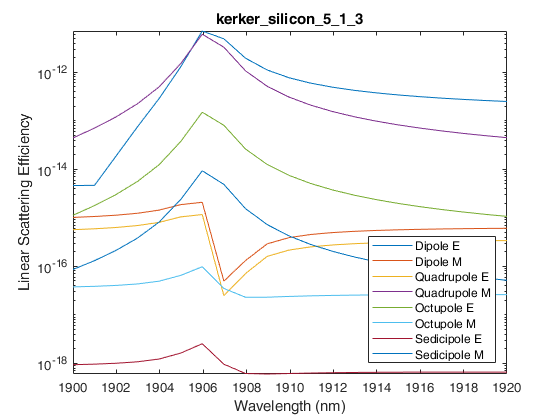

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config\sweeps');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed\NotProcessed');

symmetry_group = Mie;

for job = "evlyukhin"
    eval(job);
    load([options.output_dir_final 'derived_values.mat']);
    extra_options = matthew_extra_options(options);
    
    wlengths = 299792458./derived_values.signal.freq;

    
    fig = figure;
    
    for mpole = [symmetry_group.modes]
        switch mpole.mode.parity
            case "even" 
                results = derived_values.signal_mpole_even.l_e == mpole.mode.l &...
                    derived_values.signal_mpole_even.m_e == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_even.CscaEe(results)));
                hold on;
                results = derived_values.signal_mpole_even.l_e == mpole.mode.l &...
                    derived_values.signal_mpole_even.m_e == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_even.CscaMe(results)));
            case "odd" 
                results = derived_values.signal_mpole_odd.l_o == mpole.mode.l &...
                    derived_values.signal_mpole_odd.m_o == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_odd.CscaEo(results)));
                hold on;
                results = derived_values.signal_mpole_odd.l_o == mpole.mode.l &...
                    derived_values.signal_mpole_odd.m_o == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_odd.CscaMo(results)));
            case "mie" 
                results = derived_values.signal_mpole_mie.l == mpole.mode.l &...
                    derived_values.signal_mpole_mie.m == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_mie.CscaE(results)));
                hold on;
                results = derived_values.signal_mpole_mie.l == mpole.mode.l &...
                    derived_values.signal_mpole_mie.m == mpole.mode.m;
                semilogy(wlengths, (derived_values.signal_mpole_mie.CscaM(results)));
            otherwise
                error("Unknown multipole type");
        end
    end
    
    ylabel('Linear Scattering Efficiency');
    leg_scat3 = legend(symmetry_group.legend);
    leg_scat3.Location = 'southeast';
    xlabel('Wavelength (nm)');
    axis tight;
    title(job, 'Interpreter', 'none');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
end

   function out = Mie()
        out.legend = {'Dipole E','Dipole M', 'Quadrupole E','Quadrupole M','Octupole E',...
            'Octupole M','Sedicipole E','Sedicipole M'};
        out.modes(4).mode.l = 4;
        out.modes(4).mode.m = 1;
        out.modes(4).mode.parity = "mie";
        out.modes(3).mode.l = 3;
        out.modes(3).mode.m = 1;
        out.modes(3).mode.parity = "mie";
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 1;
        out.modes(2).mode.parity = "mie";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "mie";
        
   end
   function out = D2h()
        out.legend = {'l=1,m=1','l=2,m=0'};
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 0;
        out.modes(2).mode.parity = "even";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "odd";
        
    end
